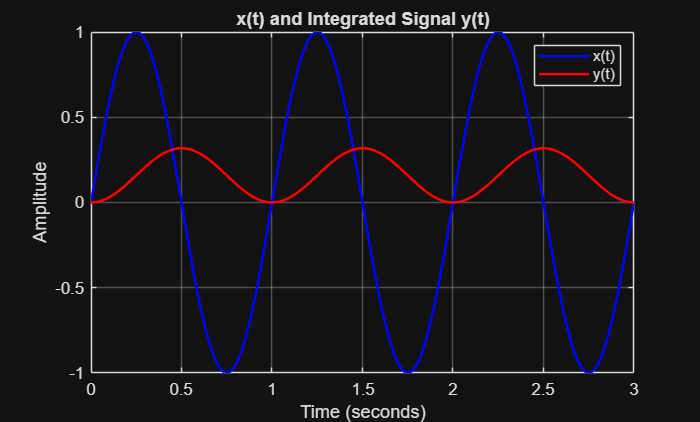

clear
clc

syms t
A = 1;
f0 = 1;

x_sym = A*sin(2*pi*f0*t);
y_sym = int(x_sym, t, 0, t);
dt = 0.01;
t_num = 0:dt:3;

x = double(subs(x_sym, t, t_num));
y = double(subs(y_sym, t, t_num));
figure
plot(t_num, x, 'b', 'LineWidth', 1.5)
hold on
plot(t_num, y, 'r', 'LineWidth', 1.5)
grid on

xlabel('Time (seconds)')
ylabel('Amplitude')
title('x(t) and Integrated Signal y(t)')
legend('x(t)', 'y(t)')

hold off

a = [1 2 3 4 5]; 					
try 
b = cumsum(a) 
end

b =      1     3     6    10    15


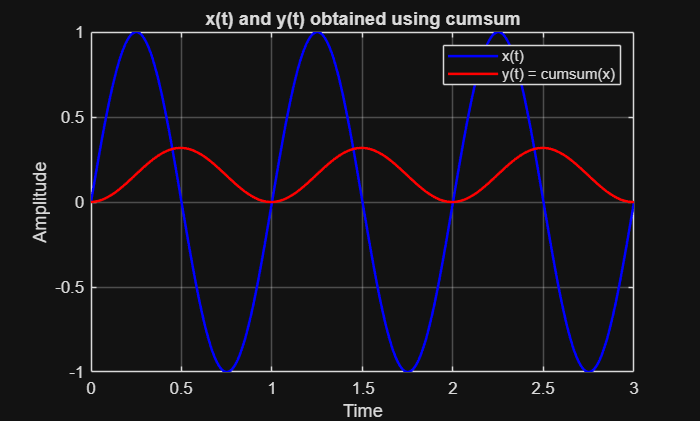

clear
clc

A = 1;
f0 = 1;
dt = 0.01;
t = 0:dt:3;
x = A*sin(2*pi*f0*t);
y = cumsum(x) * dt;   

figure
plot(t, x, 'b', 'LineWidth', 1.5)
hold on
plot(t, y, 'r', 'LineWidth', 1.5)
grid on

xlabel('Time')
ylabel('Amplitude')
title('x(t) and y(t) obtained using cumsum')
legend('x(t)', 'y(t) = cumsum(x)')
hold off

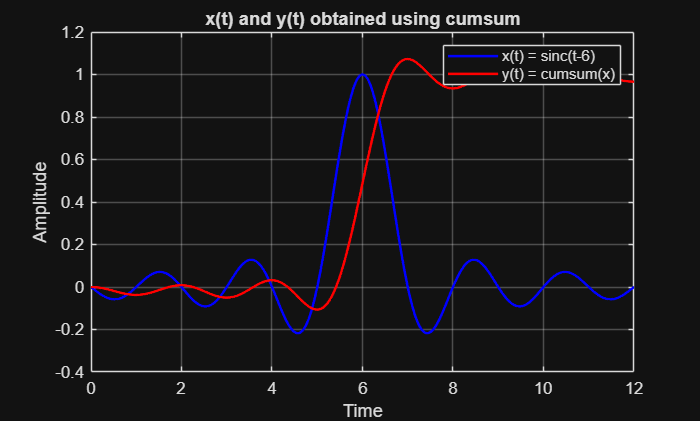


clear
clc

dt = 0.01;
t = 0:dt:12;
x = sinc(t-6);
y = cumsum(x) * dt;   

figure
plot(t, x, 'b', 'LineWidth', 1.5)
hold on
plot(t, y, 'r', 'LineWidth', 1.5)
grid on

xlabel('Time')
ylabel('Amplitude')
title('x(t) and y(t) obtained using cumsum')
legend('x(t) = sinc(t-6)', 'y(t) = cumsum(x)')
hold off

a = [1 2 3 4 5]; 
b=diff(a)

b =      1     1     1     1


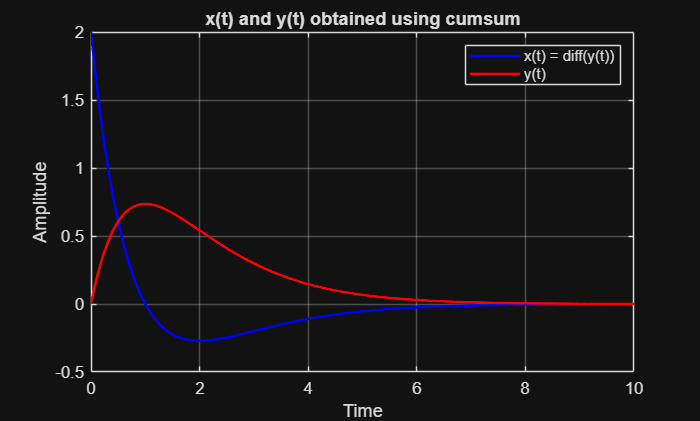

clear
clc

dt = 0.01;
t = 0:dt:10;

y = 2*t.*exp(-t);
x = 2*exp(-t).*(1 - t);

figure
plot(t, x, 'b', 'LineWidth', 1.5)
hold on
plot(t, y, 'r', 'LineWidth', 1.5)
grid on

xlabel('Time')
ylabel('Amplitude')
title('x(t) and y(t) obtained using cumsum')
legend('x(t) = diff(y(t))', 'y(t)')
hold off

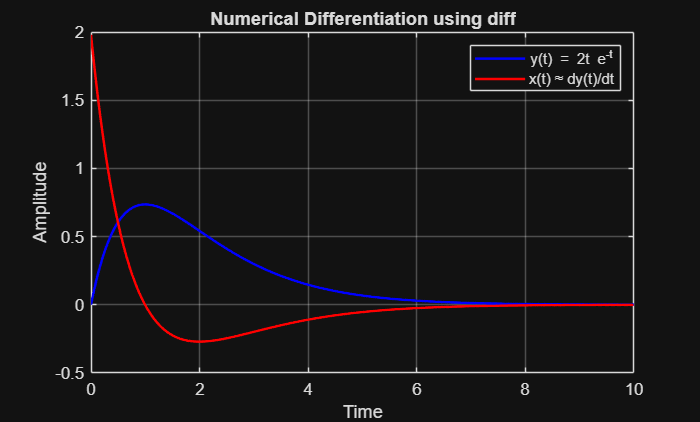


clear
clc
dt = 0.01;            
t = 0:dt:10;
y = 2*t.*exp(-t);
x = diff(y) / dt;      
t_x = t(1:end-1);

figure
plot(t, y, 'b', 'LineWidth', 1.5)
hold on
plot(t_x, x, 'r', 'LineWidth', 1.5)
grid on

xlabel('Time')
ylabel('Amplitude')
title('Numerical Differentiation using diff')
legend('y(t) = 2t e^{-t}', 'x(t) ≈ dy(t)/dt')

hold off

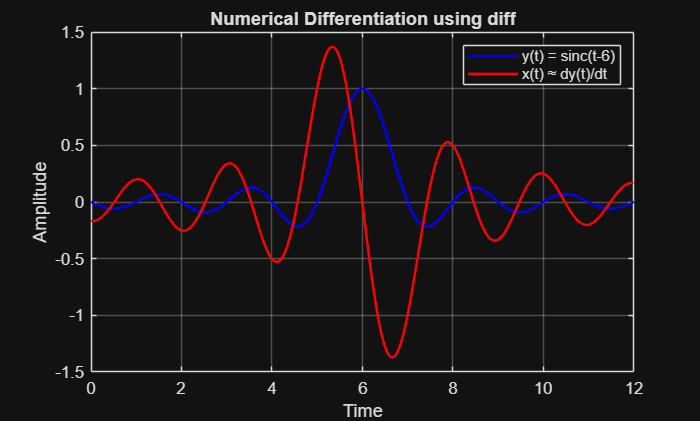


clear
clc
dt = 0.01;            
t = 0:dt:12;
y = sinc(t-6);
x = diff(y) / dt;      
t_x = t(1:end-1);

figure
plot(t, y, 'b', 'LineWidth', 1.5)
hold on
plot(t_x, x, 'r', 'LineWidth', 1.5)
grid on

xlabel('Time')
ylabel('Amplitude')
title('Numerical Differentiation using diff')
legend('y(t) = sinc(t-6)', 'x(t) ≈ dy(t)/dt')

hold off

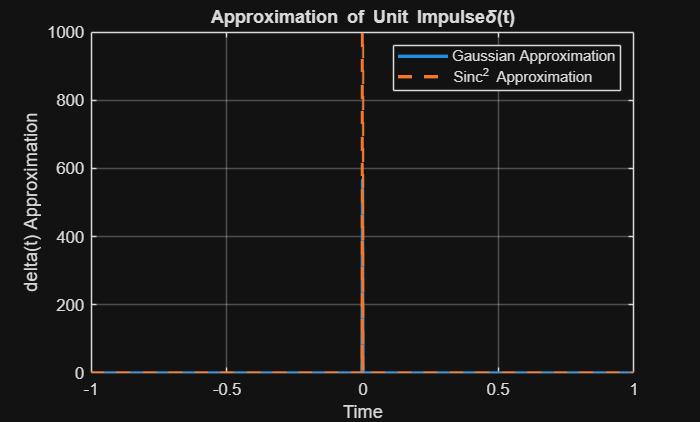


clc;
clear;
close all;
dt = 0.001;                
t = -1:dt:1;             
a = 0.001;

gauss = (1/(a*sqrt(pi))) * exp(-(t.^2)/(a^2));
sinc = (a./(pi*t).^2) .* (sin(pi*t/a)).^2;
sinc(t == 0) = 1/a;  

figure;
plot(t, gauss, 'LineWidth', 2);
hold on;
plot(t, sinc, '--', 'LineWidth', 2);
grid on;

xlabel('Time');
ylabel('delta(t) Approximation');
title('Approximation of Unit Impulse\delta(t)');
legend('Gaussian Approximation', 'Sinc^2 Approximation');


clc;
clear;
close all;
dt = 0.001;                
t = -1:dt:1;             
a = 0.001;

gauss = (1/(a*sqrt(pi))) * exp(-(t.^2)/(a^2));
sinc = (a./(pi*t).^2) .* (sin(pi*t/a)).^2;
sinc(t == 0) = 1/a; 

area_gauss = sum(gauss) * dt;
area_sinc  = sum(sinc)  * dt;

disp(['Area under Gaussian approximation = ', num2str(area_gauss)]);

Area under Gaussian approximation = 1.0001


disp(['Area under Sinc^2 approximation   = ', num2str(area_sinc)]);

Area under Sinc^2 approximation   = 1


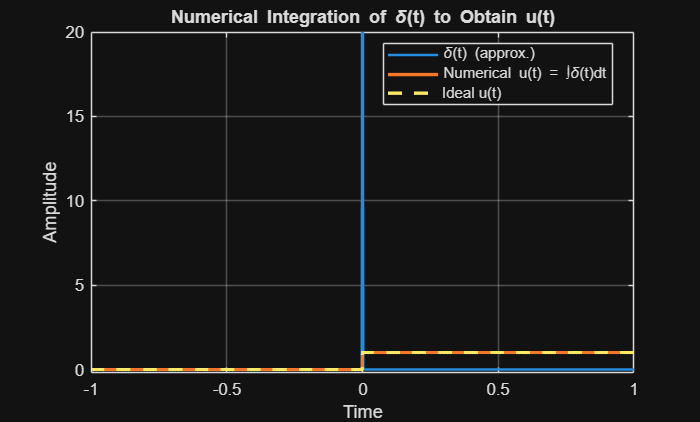


clc;
clear;
dt = 0.001;                
t = -1:dt:1;             
a = 0.001;
gauss = (1/(a*sqrt(pi))) * exp(-(t.^2)/(a^2));
u_num = cumsum(gauss) * dt;
u_ideal = double(t >= 0);

figure;
plot(t,gauss, 'LineWidth', 1.5);
hold on;
plot(t, u_num, 'LineWidth', 2);
plot(t, u_ideal, '--', 'LineWidth', 2);
grid on;

xlabel('Time');
ylabel('Amplitude');
title('Numerical Integration of \delta(t) to Obtain u(t)');
legend('\delta(t) (approx.)', 'Numerical u(t) = ∫\delta(t)dt', 'Ideal u(t)', 'Location', 'best');
ylim([-0.2 20]); 

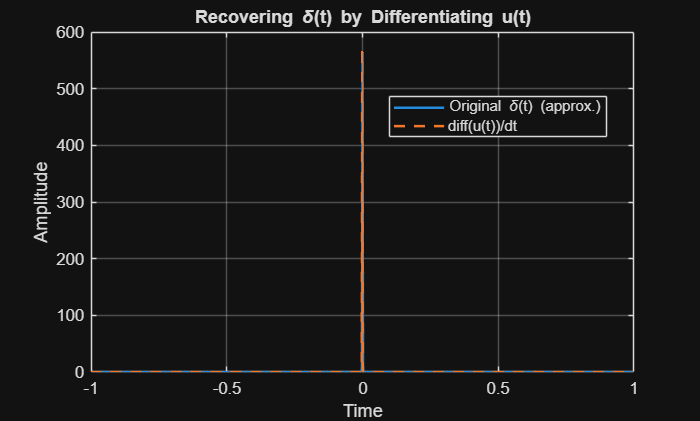

clc;
clear;
close all;
dt = 0.001;
t = -1:dt:1;
a = 0.001;

gauss = (1/(a*sqrt(pi))) * exp(-(t.^2)/(a^2));
num = cumsum(gauss) * dt;
delta_u = diff(num) / dt;
t_dif = t(1:end-1);
figure;
plot(t, gauss, 'LineWidth', 1.5); 
hold on;
plot(t_dif, delta_u, '--', 'LineWidth', 1.5);
grid on;

xlabel('Time');
ylabel('Amplitude');
title('Recovering \delta(t) by Differentiating u(t)');
legend('Original \delta(t) (approx.)', 'diff(u(t))/dt', 'Location', 'best');
ylim([0 600]);